### MATLAB Practice

Symbolic variable

syms z;
f = @(x)log(x);
f(6);
% use with symbolic variables
subs(f(z), z, 3)

$$ans = \log\left(3\right)$$

% specify sig figs
vpa(subs(f(z), z, 3),5)

$$ans = 1.0986$$

Anonymous function

func = @(x,y)cos(x+y);
func(2,3);

More stuff

% numerical integration
f = @(x) 1./sqrt(1+x.^2);
xmin = 0;
xmax = 10;
x = linspace(xmin, xmax, 1000);
%plot(x, f(x));
I = integral(f, xmin, xmax);

ODE's

syms g(x);
% takes derivative of symbolic function
%ode = diff(g,x,1) == 1/x;
ode = diff(g,x,1) + 3*diff(g,x,2) == 1/x;
% boundary condition
cond1 = g(1) == 1;
% takes symbolic dfq, and conditions, solves it
dsolve(ode, [cond1])

$$ans = {\mathrm{e}}^{-\frac{x}{3}}\,\left(\text{ei}\left(\frac{1}{3}\right)+{\mathrm{e}}^{1/3}+C_{3}\,{\mathrm{e}}^{1/3}\right)-{\mathrm{e}}^{-\frac{x}{3}}\,\left(\text{ei}\left(\frac{x}{3}\right)-{\mathrm{e}}^{x/3}\,\log\left(x\right)+C_{3}\,{\mathrm{e}}^{x/3}\right)$$

Set of DE's

syms g1(x) g2(x);
% k is a parameter/solution/condition
syms k;
ode1 = diff(g1, x, 1) == x+k;
ode2 = diff(g2, x, 2) == x+k;
% put them into array
odes = [ode1, ode2]

$$odes(x) = \left(\begin{array}{cc} \frac{\partial }{\partial x}g_{1}\left(x\right)=k+x & \frac{\partial^{2}}{\partial x^{2}}g_{2}\left(x\right)=k+x \end{array}\right)$$

% solving them, solutions put into struct
sol = dsolve(odes);
sol.g1

$$ans = C_{4}+\frac{x\,\left(2\,k+x\right)}{2}$$

sol.g2

$$ans = C_{6}+\frac{x\,\left(x^{2}+3\,k\,x+6\,C_{5}\right)}{6}$$

Doing things non-symbolically

dgdx = @(x,g) 1/x;
% bounds of integral
xspan = [1 10];
% tell the algorithm where to start (initial conditions?)
g0 = 1;
% lots of different ode functions, 45 is standard one
sol = ode45(dgdx, xspan, g0);
X = linspace(1, 10, 1000);
% plot computed function g(x) over array X
plot(X, deval(sol, X))
% evaluate specific input
deval(sol, 4)

ans =        2.3863


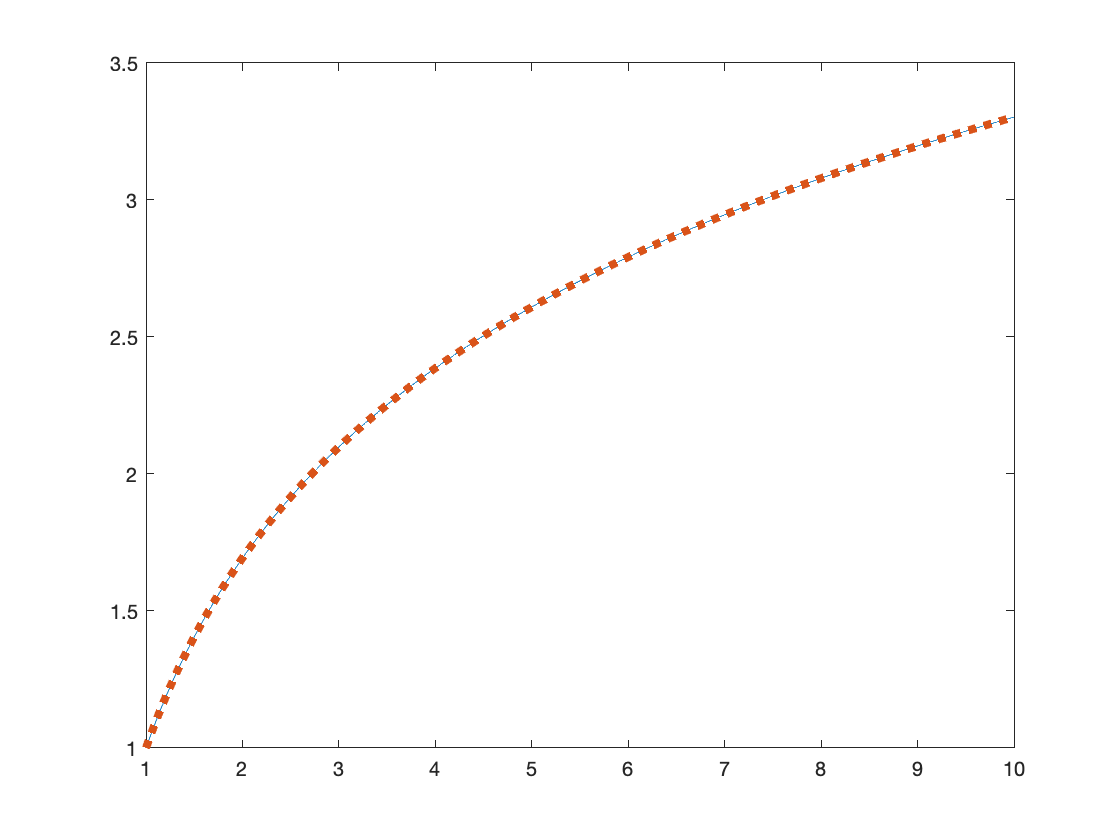

hold on
% zoom in to see that our computed function is a little off from actual function
plot(X, log(X)+1, 'LineWidth', 4, 'LineStyle', ':')

Solving system equations

% standard linear equations
A = [1 8; 1 7];
b = [12 ; 31];
linsolve(A,b);
% for symbolic equations, use solve(A,b)
% finding roots of functions
f = @(x) x.^3-2.*x+0.5;
x = linspace(-3,3,1000);
plot(x, f(x))
yline(0);
x0 = -2;
xroot = fzero(f,x0);
xline(xroot);
% what about the other roots?
x0 = -1.5;
xroot = fzero(f,x0);
xline(xroot)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: -1.5257
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


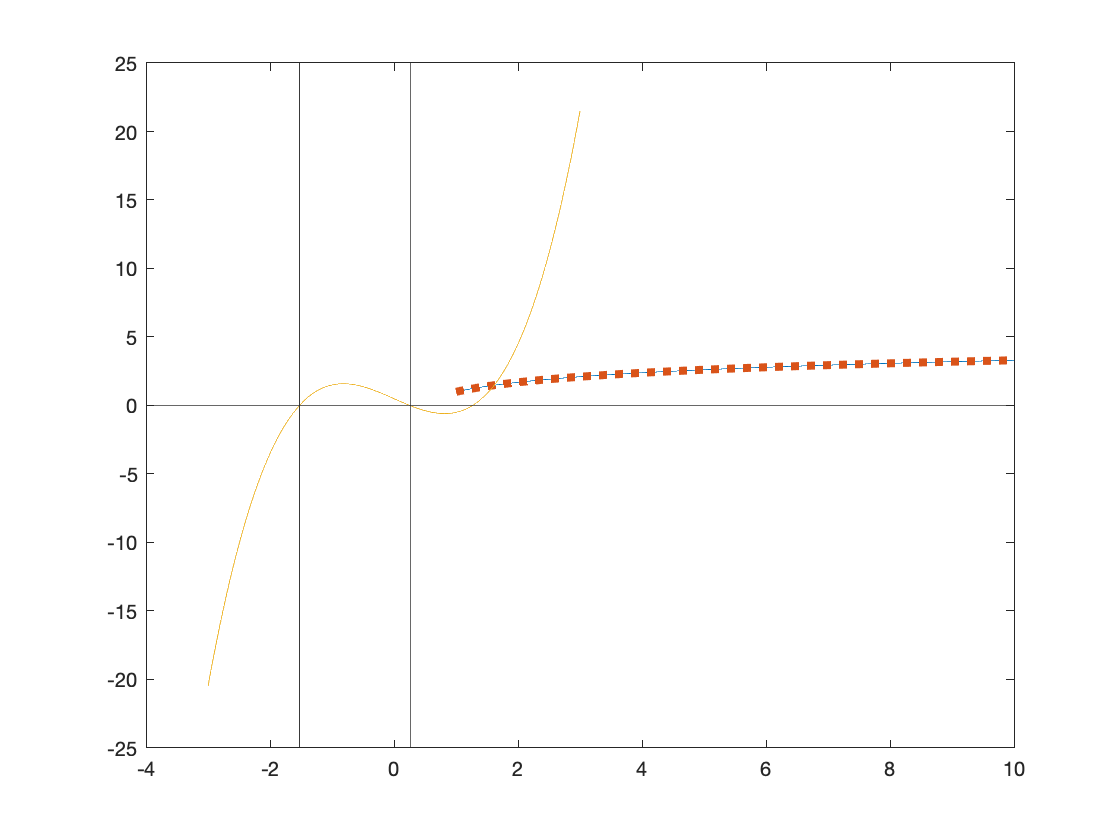

x0 = 0;
xroot = fzero(f,x0);
xline(xroot);

Roots of non-linear system of equations

syms x y;
eq1 = x^2+y^2 - 5; % = 0 is implicit, defining circle with radius 5
eq2 = x;
eqns = [eq1, eq2];
sol = vpasolve(eqns, [x,y], [0,0]);
% solutions are intersection points
sol.x

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

sol.y

$$ans = \left(\begin{array}{c} -2.2360679774997896964091736687313\\ 2.2360679774997896964091736687313 \end{array}\right)$$

Polyfit - super useful 

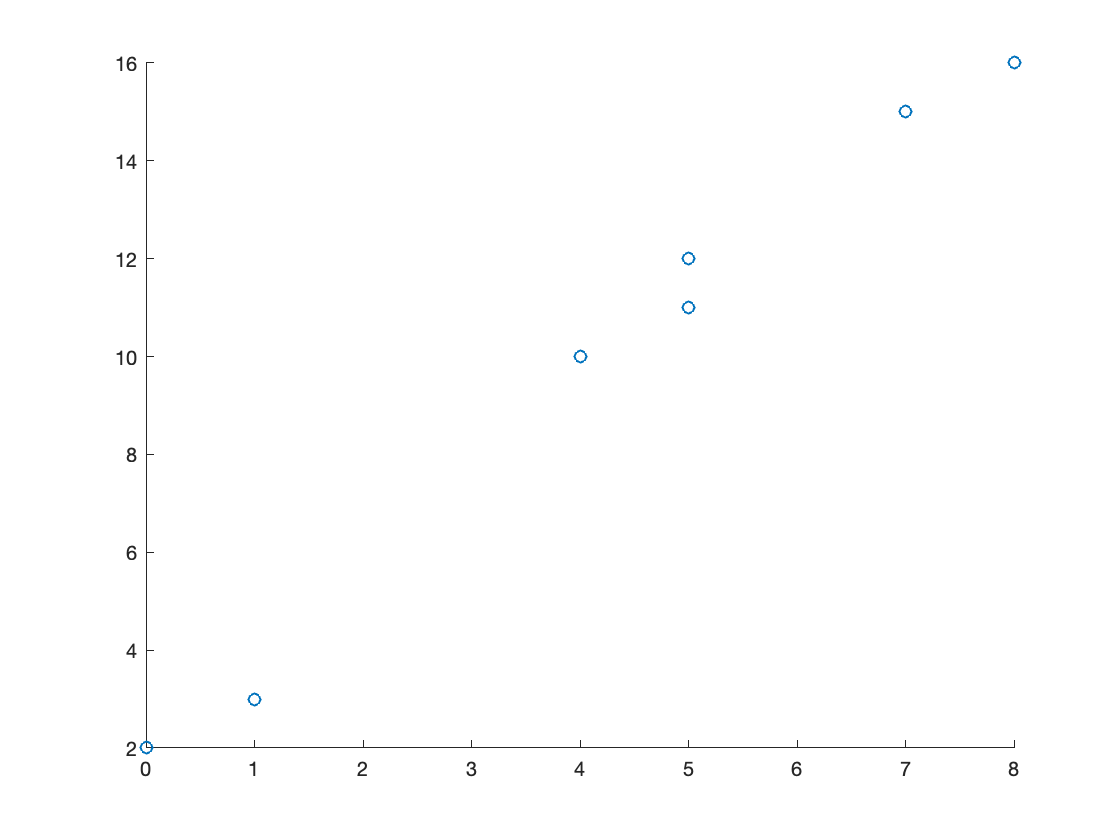

x = [0 1 4 5 5 7 8];
y = [2 3 10 12 11 15, 16];
scatter(x,y);

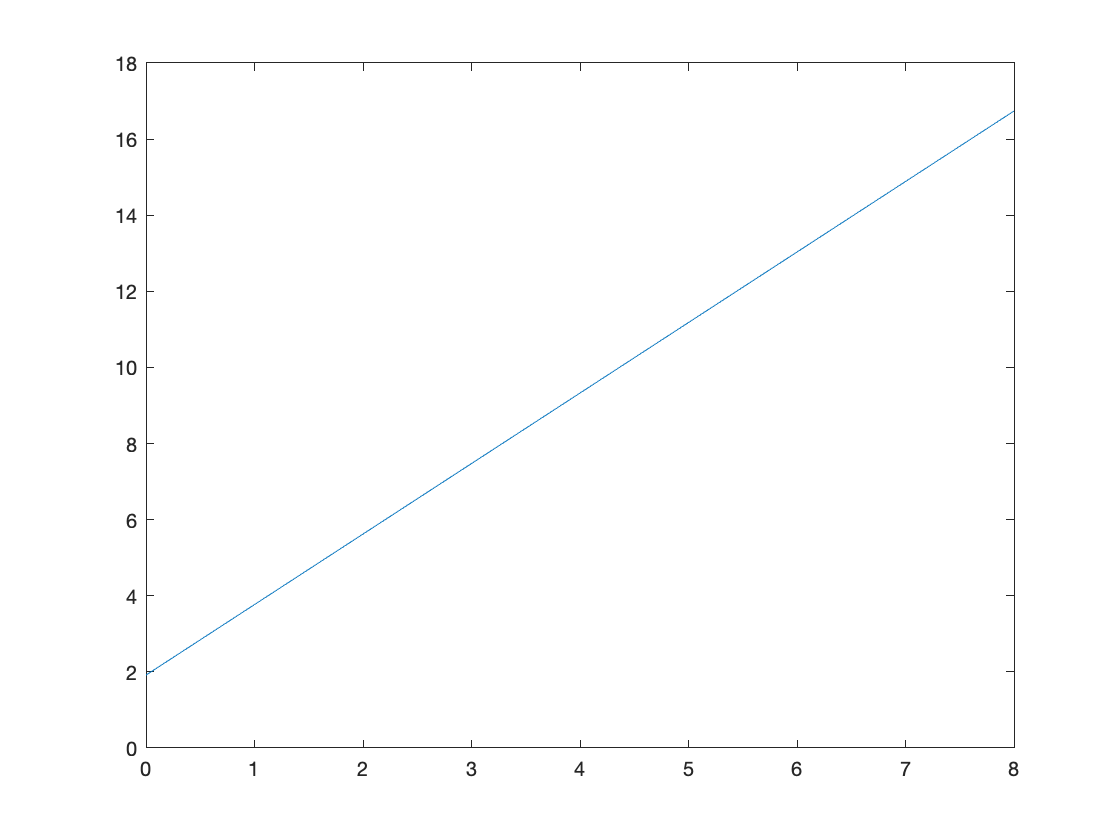

% third term is degree of polynomial
coeffs = polyfit(x, y, 1);
% plotting the fit
f = @(x) coeffs(1)*x + coeffs(2);
plot(x, f(x))

Normal functions

[output_1, output_2] = funct(3,4)

output_1 =      6


output_2 =     24


function [output_1, output_2] = funct(input_1, input_2)
    output_1 = input_1*2;
    output_2 = input_2*6;
    [output_1, output_2];
end